%% === SETUP ===
parent_folder = '/Users/shaheenkabir/Bcd_analysis/BR81/BR81_25';
output_parent = '/Users/shaheenkabir/Bcd_analysis/BR81/BR81_25';
if ~exist(output_parent, 'dir')
    mkdir(output_parent);
end

% === Pick single file ===
filename = fullfile(parent_folder, 'BR81_25_1.tif');  % Change this
[~, baseName, ~] = fileparts(filename);

%Factor2 = 80/80;  % exposure correction
%Factor = 0.6431;  % micron/pixel

fprintf('Processing file: %s\n', filename);

Processing file: /Users/shaheenkabir/Bcd_analysis/BR81/BR81_25/BR81_25_1.tif


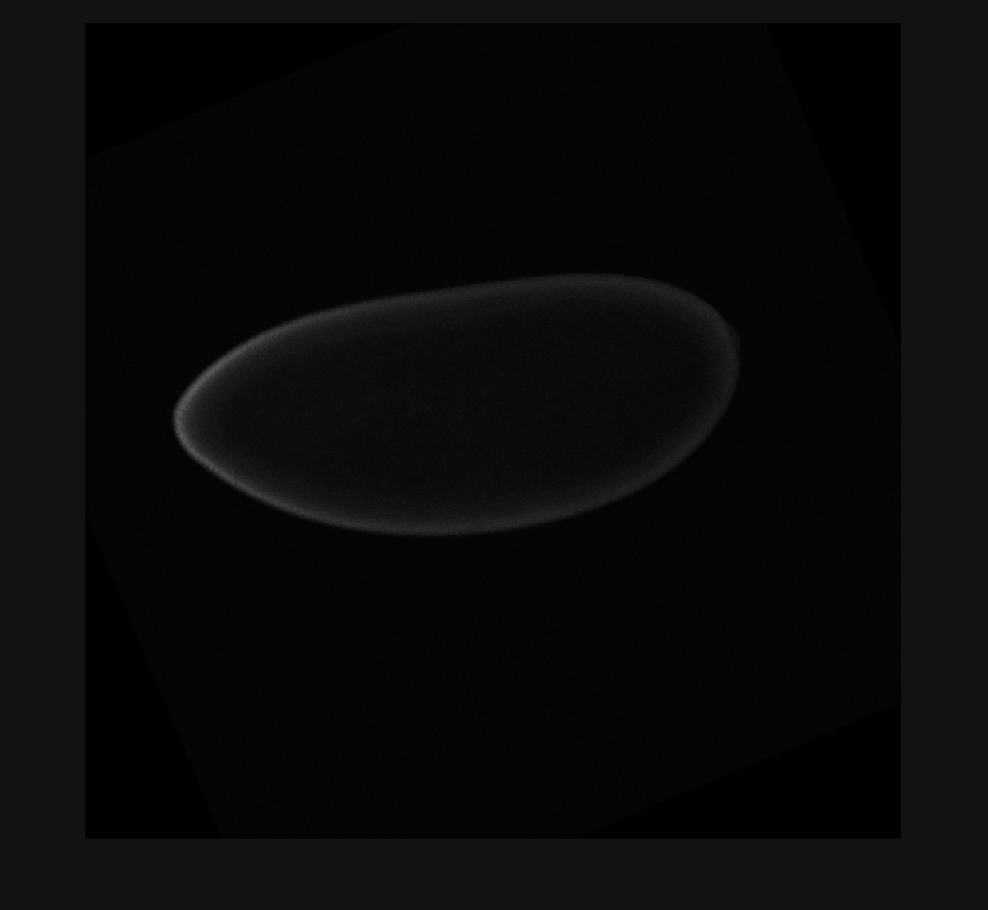


% === Create output folder ===
output_folder_pic = fullfile(output_parent, "masks")
if ~exist(output_folder_pic, 'dir')
    mkdir(output_folder_pic)
end
output_folder = fullfile(output_parent, baseName);
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

%% === Load channels ===
bcd  = imread(filename, 2);
figure; imshow(bcd);

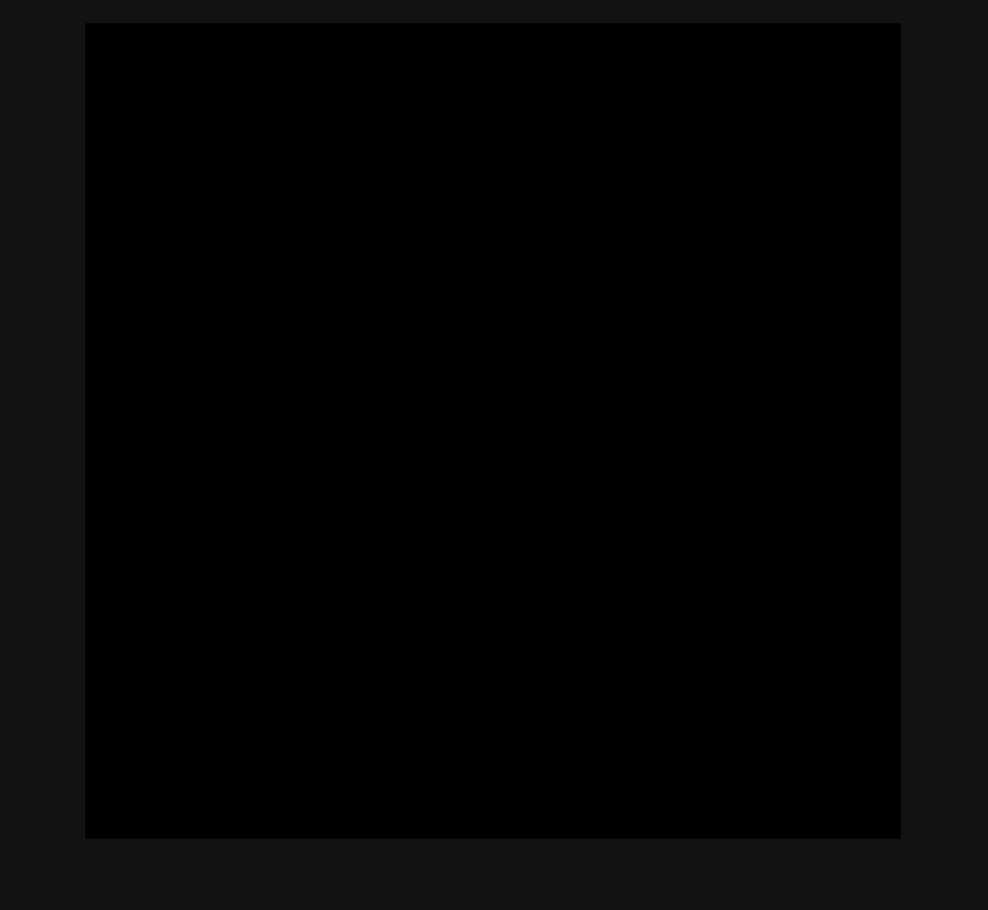


imwrite(bcd, fullfile(output_folder, strcat(baseName, "_Bcd_raw.tif")));

%bcd = adapthisteq(bcd);
threshold = graythresh(imadjust(bcd));
%threshold = 0.2;
mask = imbinarize(bcd, threshold);
figure; imshow(mask);


stats = regionprops(mask, "all");
embryoArea = [stats.Area];
[~, embryoID] = max(embryoArea);

    % === Nuclear mask ===
nmask = zeros(size(mask));
nmask(stats(embryoID).PixelIdxList) = 1;

At least one index is required.

figure; imshow(nmask);

imwrite(nmask, fullfile(output_folder_pic, strcat(baseName, "_nmask.png")));

bcd = bcd .* uint8(nmask);
figure; imshow(bcd);

theta = -stats(embryoID).Orientation;
bcd = imrotate(bcd,theta);
U = imrotate(nmask, theta);

figure; imshow(bcd);
figure; imshow(U);

% Finding edge in mask
BW = edge(U, 'canny');
figure; imshow(BW);
m0 = find(sum(BW, 1) > 0);
n0 = find(sum(BW, 2) > 0);

bcd1  = imcrop(bcd, [min(m0), min(n0), max(m0)-min(m0), max(n0)-min(n0)]);
%theta2 = 180 * double(max(max(bcd(:,1:50))) < max(max(bcd(:,end-49:end))));
%bcd1  = imrotate(bcd1, theta2, 'crop');
figure; imshow(bcd1);

bcd1 = bcd;
% Finding edge of original pic
BW1 = edge(bcd1,"canny");
figure; imshow(BW1);

m1 = find(sum(BW1, 1) > 0);
n1 = zeros(1, length(m1));
for j = 1:length(m1)
    n1(j) = min(find(BW1(:, m1(j)) > 0));
end
n2 = smooth(m1, n1, 0.07, 'rloess')';

% Find midline
Bins = 50;
EL = max(m1) - min(m1) + 1;
L = floor(EL / Bins);
gama = atan(gradient(n2));
radius = 10;
centroidx = round(m1 - sin(gama) * radius);
centroidy = round(n2 + cos(gama) * radius);

centroidx1 = zeros(1, Bins);
centroidy1 = zeros(1, Bins);
z = zeros(1, Bins);

for j = 1:Bins
        idx = ceil(0.5*EL - (Bins+1)/2*L + j*L);
        centroidx1(j) = centroidx(idx);
        centroidy1(j) = centroidy(idx);
        z(j) = mean2([bcd1(centroidy1(j), centroidx1(j)-4:centroidx1(j)+4), ...
                      bcd1(centroidy1(j)-1, centroidx1(j)-4:centroidx1(j)+3), ...
                      bcd1(centroidy1(j)+1, centroidx1(j)-3:centroidx1(j)+4), ...
                      bcd1(centroidy1(j)-2, centroidx1(j)-3:centroidx1(j)+3), ...
                      bcd1(centroidy1(j)+2, centroidx1(j)-3:centroidx1(j)+3), ...
                      bcd1(centroidy1(j)-3, centroidx1(j)-2:centroidx1(j)+3), ...
                      bcd1(centroidy1(j)+3, centroidx1(j)-3:centroidx1(j)+2), ...
                      bcd1(centroidy1(j)-4, centroidx1(j)-2:centroidx1(j)+2), ...
                      bcd1(centroidy1(j)+4, centroidx1(j)-2:centroidx1(j)+2)]);
end
    figure; imshow(bcd1); hold on;
    scatter(m1, n2, 'r.'); hold on;
    scatter(centroidx1, centroidy1, 'b.');

    f = figure; imshow(bcd1); hold on;
    scatter(m1, n2, 'r.');hold on;
    scatter(centroidx1, centroidy1, 'b.');
    saveas(f, fullfile(output_folder, strcat(baseName, "_samplig_points.png")));
    close(f);


% Absolute

L2 = round(900 / Bins);
    Bins2 = floor(EL / L2);
    z2 = zeros(1, Bins2);
    centroidx2 = zeros(1, Bins2);
    centroidy2 = zeros(1, Bins2);

    for j = 1:Bins2
        idx = j*L2 - ceil(L2/2) + 1;
        centroidx2(j) = centroidx(idx);
        centroidy2(j) = centroidy(idx);
        z2(j) = mean2([bcd1(centroidy2(j), centroidx2(j)-4:centroidx2(j)+4), ...
                       bcd1(centroidy2(j)-1, centroidx2(j)-4:centroidx2(j)+3), ...
                       bcd1(centroidy2(j)+1, centroidx2(j)-3:centroidx2(j)+4), ...
                       bcd1(centroidy2(j)-2, centroidx2(j)-3:centroidx2(j)+3), ...
                       bcd1(centroidy2(j)+2, centroidx2(j)-3:centroidx2(j)+3), ...
                       bcd1(centroidy2(j)-3, centroidx2(j)-2:centroidx2(j)+3), ...
                       bcd1(centroidy2(j)+3, centroidx2(j)-3:centroidx2(j)+2), ...
                       bcd1(centroidy2(j)-4, centroidx2(j)-2:centroidx2(j)+2), ...
                       bcd1(centroidy2(j)+4, centroidx2(j)-2:centroidx2(j)+2)]);
    end

    % === Store ===
    Data.EL = EL;
    Data.relx = centroidx1 - min(m1) + 1;
    Data.rely = centroidy1 - min(n2) + 1;
    Data.relBcd = double(z);
    Data.absx = centroidx2 - min(m1) + 1;
    Data.absy = centroidy2 - min(n2) + 1;
    Data.absBcd = double(z2);
    Data.name = baseName;


relX = Data.relx / Data.EL;
absX = Data.absx;
relBcd = Data.relBcd;
absBcd = Data.absBcd;

Trel = table(relX', relBcd', 'VariableNames', {'AP_Position', 'Intensity'});
Tabs = table(absX', absBcd', 'VariableNames', {'AP_Position', 'Intensity'});

writetable(Trel, fullfile(output_folder, [baseName '_Bcd_profile_rel.xlsx']));
%writetable(Tabs, fullfile(output_folder, [baseName '_Bcd_profile_abs.xlsx']));

fprintf('✅ Saved results for: %s\n', baseName);
disp('Done ✅');














